## Condiciones iniciales de avance

syms a1(t) a2(t) a3(t) a4(t) a5(t) T A
syms v1(t) v2(t) v3(t) v4(t) v5(t) 
syms x1(t) x2(t) x3(t) x4(t) x5(t)
assume(T>0)
assume(A>0)
g=9.81;
xMax=0.1

xMax = 0.1000

aMax=g/5

aMax = 1.9620

A=aMax;


## Aceleración

a1(t)=10*A/T*t;

a2(t)=A;

a3(t)=-10*A/T*t;
Ca3=A-a3(4*T/10);
a3(t)=a3(t)+Ca3;
a4(t)=-A;
a5(t)=10*A/T*t;
Ca5=a4(9*T/10)-a5(9*T/10);
a5(t)=a5(t)+Ca5;
fprintf('Función de aceleración:')

Función de aceleración:

a(t)=piecewise((0<=t<T/10),a1,(T/10<=t<4*T/10),a2,(4*T/10<=t<6*T/10),a3,(6*T/10<=t<9*T/10),a4,(9*T/10<=t<=T),a5)

$$a(t) = \begin{array}{l} \left\{ \begin{array}{cl} \sigma_{1} & \text{ if }10\,t<T\wedge 0\leq t\\ \frac{981}{500} & \text{ if }T\leq 10\,t\wedge 5\,t<2\,T\\ \frac{981}{100}-\sigma_{1} & \text{ if }5\,t<3\,T\wedge 2\,T\leq 5\,t\\ -\frac{981}{500} & \text{ if }10\,t<9\,T\wedge 3\,T\leq 5\,t\\ \sigma_{1}-\frac{981}{50} & \text{ if }t\leq T\wedge 9\,T\leq 10\,t \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{981\,t}{50\,T} \end{array}$$

## Velocidad

v1(t)=int(a1);

v2(t)=int(a2);
Cv2=v1(T/10)-v2(T/10);
v2(t)=v2(t)+Cv2;

v3(t)=int(a3);
Cv3=v2(4*T/10)-v3(4*T/10);
v3(t)=v3(t)+Cv3;

v4(t)=int(a4);
Cv4=v3(6*T/10)-v4(6*T/10);
v4(t)=v4(t)+Cv4;

v5(t)=int(a5);
Cv5=v4(9*T/10)-v5(9*T/10);
v5(t)=v5(t)+Cv5;

fprintf('Función de velocidad:')

Función de velocidad:

v(t)=piecewise((0<=t<T/10),v1,(T/10<=t<4*T/10),v2,(4*T/10<=t<6*T/10),v3,(6*T/10<=t<9*T/10),v4,(9*T/10<=t<=T),v5)

$$v(t) = \left\{ \begin{array}{cl} \frac{981\,t^{2}}{100\,T} & \text{ if }10\,t<T\wedge 0\leq t\\ \frac{981\,t}{500}-\frac{981\,T}{10000} & \text{ if }T\leq 10\,t\wedge 5\,t<2\,T\\ -\frac{16677\,T}{10000}-\frac{t\,\left(\frac{981\,t}{T}-981\right)}{100} & \text{ if }5\,t<3\,T\wedge 2\,T\leq 5\,t\\ \frac{18639\,T}{10000}-\frac{981\,t}{500} & \text{ if }10\,t<9\,T\wedge 3\,T\leq 5\,t\\ \frac{981\,T}{100}+\frac{t\,\left(\frac{981\,t}{2\,T}-981\right)}{50} & \text{ if }t\leq T\wedge 9\,T\leq 10\,t \end{array}\right.$$

## Desplazamiento


x1(t)=int(v1);

x2(t)=int(v2);
Cx2=x1(T/10)-x2(T/10);
x2(t)=x2(t)+Cx2;

x3(t)=int(v3);
Cx3=x2(4*T/10)-x3(4*T/10);
x3(t)=x3(t)+Cx3;

x4(t)=int(v4);
Cx4=x3(6*T/10)-x4(6*T/10);
x4(t)=x4(t)+Cx4;

x5(t)=int(v5);
Cx5=x4(9*T/10)-x5(9*T/10);
x5(t)=x5(t)+Cx5;

fprintf('Función de desplazamiento:')

Función de desplazamiento:

x(t)=piecewise((0<=t<T/10),x1,(T/10<=t<4*T/10),x2,(4*T/10<=t<6*T/10),x3,(6*T/10<=t<9*T/10),x4,(9*T/10<=t<=T),x5)

$$x(t) = \begin{array}{l} \left\{ \begin{array}{cl} \sigma_{1} & \text{ if }10\,t<T\wedge 0\leq t\\ \frac{327\,T^{2}}{100000}-\frac{981\,t\,\left(T-10\,t\right)}{10000} & \text{ if }T\leq 10\,t\wedge 5\,t<2\,T\\ \frac{4251\,T^{2}}{20000}-\frac{16677\,T\,t}{10000}+\frac{981\,t^{2}}{200}-\sigma_{1} & \text{ if }5\,t<3\,T\wedge 2\,T\leq 5\,t\\ \frac{981\,t\,\left(19\,T-10\,t\right)}{10000}-\frac{49377\,T^{2}}{100000} & \text{ if }10\,t<9\,T\wedge 3\,T\leq 5\,t\\ \frac{327\,t\,\left(3\,T^{2}-3\,T\,t+t^{2}\right)}{100\,T}-\frac{3597\,T^{2}}{1250} & \text{ if }t\leq T\wedge 9\,T\leq 10\,t \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{327\,t^{3}}{100\,T} \end{array}$$

## Solución de tMax

f=xMax/2==x(T/2);

tMax=solve(f,T);


a=subs(a,T,tMax);
v=subs(v,T,tMax);
x=subs(x,T,tMax);
a(t)=piecewise((0<=t<tMax),a(t),(tMax<=t<=2*tMax),-a(t-tMax))

$$a(t) = \begin{array}{l} \left\{ \begin{array}{cl} \sigma_{1} & \text{ if }t\in \left[0,\frac{\sqrt{1090}}{654}\right)\\ \frac{981}{500} & \text{ if }t\in \left[\frac{\sqrt{1090}}{654},\sigma_{6}\right)\\ \frac{981}{100}-\sigma_{1} & \text{ if }t\in \left[\sigma_{6},\frac{\sqrt{1090}}{109}\right)\\ -\frac{981}{500} & \text{ if }t\in \left[\frac{\sqrt{1090}}{109},\sigma_{7}\right)\\ \sigma_{1}-\frac{981}{50} & \text{ if }t\in \left[\sigma_{7},\sigma_{9}\right)\\ -\sigma_{8} & \text{ if }t\in \left[\sigma_{9},\sigma_{3}\right)\\ -\frac{981}{500} & \text{ if }t\in \left[\sigma_{3},\sigma_{5}\right)\\ \sigma_{8}-\frac{981}{100} & \text{ if }t\in \left[\sigma_{5},\sigma_{4}\right)\\ \frac{981}{500} & \text{ if }t\in \left[\sigma_{4},\sigma_{2}\right)\\ \frac{981}{50}-\sigma_{8} & \text{ if }t\leq \frac{10\,\sqrt{1090}}{327}\wedge \sigma_{2}\leq t \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{2943\,\sqrt{1090}\,t}{2500}\\ \sigma_{2}=\frac{19\,\sqrt{1090}}{654}\\ \sigma_{3}=\frac{11\,\sqrt{1090}}{654}\\ \sigma_{4}=\frac{8\,\sqrt{1090}}{327}\\ \sigma_{5}=\frac{7\,\sqrt{1090}}{327}\\ \sigma_{6}=\frac{2\,\sqrt{1090}}{327}\\ \sigma_{7}=\frac{3\,\sqrt{1090}}{218}\\ \sigma_{8}=\frac{2943\,\sqrt{1090}\,\left(t-\sigma_{9}\right)}{2500}\\ \sigma_{9}=\frac{5\,\sqrt{1090}}{327} \end{array}$$

v(t)=piecewise((0<=t<tMax),v(t),(tMax<=t<=2*tMax),-v(t-tMax))

$$v(t) = \begin{array}{l} \left\{ \begin{array}{cl} \frac{2943\,\sqrt{1090}\,t^{2}}{5000} & \text{ if }t\in \left[0,\frac{\sqrt{1090}}{654}\right)\\ \frac{981\,t}{500}-\frac{3\,\sqrt{1090}}{2000} & \text{ if }t\in \left[\frac{\sqrt{1090}}{654},\sigma_{6}\right)\\ -\sigma_{1}-\frac{t\,\left(\frac{2943\,\sqrt{1090}\,t}{50}-981\right)}{100} & \text{ if }t\in \left[\sigma_{6},\frac{\sqrt{1090}}{109}\right)\\ \frac{57\,\sqrt{1090}}{2000}-\frac{981\,t}{500} & \text{ if }t\in \left[\frac{\sqrt{1090}}{109},\sigma_{7}\right)\\ \sigma_{8}+\frac{t\,\left(\frac{2943\,\sqrt{1090}\,t}{100}-981\right)}{50} & \text{ if }t\in \left[\sigma_{7},\sigma_{10}\right)\\ -\frac{2943\,\sqrt{1090}\,{\left(t-\sigma_{10}\right)}^{2}}{5000} & \text{ if }t\in \left[\sigma_{10},\sigma_{3}\right)\\ \frac{63\,\sqrt{1090}}{2000}-\frac{981\,t}{500} & \text{ if }t\in \left[\sigma_{3},\sigma_{5}\right)\\ \sigma_{1}+\frac{\left(t-\sigma_{10}\right)\,\left(\frac{\sigma_{9}}{50}-981\right)}{100} & \text{ if }t\in \left[\sigma_{5},\sigma_{4}\right)\\ \frac{981\,t}{500}-\frac{117\,\sqrt{1090}}{2000} & \text{ if }t\in \left[\sigma_{4},\sigma_{2}\right)\\ -\sigma_{8}-\frac{\left(t-\sigma_{10}\right)\,\left(\frac{\sigma_{9}}{100}-981\right)}{50} & \text{ if }t\leq \frac{10\,\sqrt{1090}}{327}\wedge \sigma_{2}\leq t \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{51\,\sqrt{1090}}{2000}\\ \sigma_{2}=\frac{19\,\sqrt{1090}}{654}\\ \sigma_{3}=\frac{11\,\sqrt{1090}}{654}\\ \sigma_{4}=\frac{8\,\sqrt{1090}}{327}\\ \sigma_{5}=\frac{7\,\sqrt{1090}}{327}\\ \sigma_{6}=\frac{2\,\sqrt{1090}}{327}\\ \sigma_{7}=\frac{3\,\sqrt{1090}}{218}\\ \sigma_{8}=\frac{3\,\sqrt{1090}}{20}\\ \sigma_{9}=2943\,\sqrt{1090}\,\left(t-\sigma_{10}\right)\\ \sigma_{10}=\frac{5\,\sqrt{1090}}{327} \end{array}$$

x(t)=piecewise((0<=t<tMax),x(t),(tMax<=t<=2*tMax),x(tMax)-x(t-tMax))

tMax=2*tMax;
fprintf('Tiempo de ciclo %.3f s',tMax)

Tiempo de ciclo 1.010 s

## Gráficas

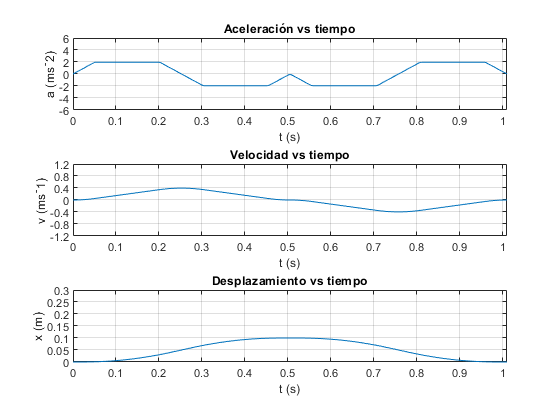

ts=linspace(0,tMax,200);
subplot(3,1,1)

plot(ts,a(ts))
title('Aceleración vs tiempo')
grid on
xlabel('t (s)')
ylabel('a (ms^-2)')
ylim([-6 6])
xlim([0 double(tMax)])
yticks(-6:2:6)


subplot(3,1,2)

plot(ts,v(ts))
title('Velocidad vs tiempo')
grid on
xlabel('t (s)')
ylabel('v (ms^-1)')
ylim([-1.2 1.2])
xlim([0 double(tMax)])
yticks(-1.2:0.4:1.2)

subplot(3,1,3)

plot(ts,x(ts))
title('Desplazamiento vs tiempo')
grid on
xlabel('t (s)')
ylabel('x (m)')
ylim([0 0.30])
xlim([0 double(tMax)])
yticks(0:0.05:0.30)